## Image Segmentation Example

### First, send a job to the cluster using file "ImageSeg.m" to segment the image using the cluster. 

job = batch("ImageSeg");

Wait for the job to complete.

wait(job);

Retrieve the segmentation mask from the batch job.

jobResult = load(job);

segmentationMask = jobResult.segMask;

Display the segmentation mask.

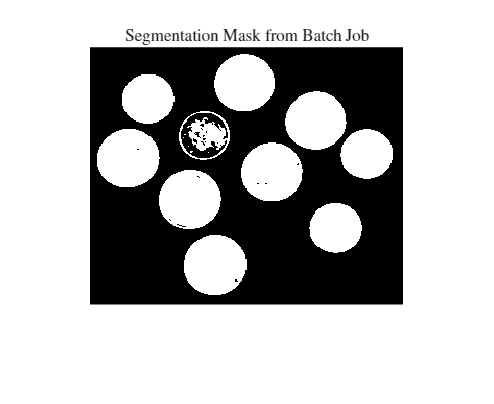

figure;
imshow(segmentationMask);
title('Segmentation Mask from Batch Job');

Don't forget to clean up the job to free up space for others.

delete(job);

### Next, using the retrieved mask, we calculate the area (pixels) using interactive pool (parfor)

Identify connected components in the segmentation mask.

CC = bwconncomp(segmentationMask);
numRegions = CC.NumObjects;

Preallocate an array to hold the area of each region.

regionAreas = zeros(1, numRegions);

Open a parallel pool (using one worker per user to share resources).

pool = parpool("Cess", 1);

Starting parallel pool (parpool) using the 'Cess' profile ...
Connected to parallel pool with 1 workers.


Use a parfor loop to compute the area (number of pixels) for each region.

parfor idx = 1:numRegions
    % Each component's pixel indices are stored in CC.PixelIdxList{idx}
    regionAreas(idx) = numel(CC.PixelIdxList{idx});
end

Display the computed region areas.

disp('Area (in pixels) for each segmented region:');

Area (in pixels) for each segmented region:


disp(regionAreas);

        2649        1854        2667         964           1           2        2748           1           5           1        2510        2587        2544        1893        1864



Close the parallel pool.

delete(pool);

Parallel pool using the 'Cess' profile is shutting down.
